f = @(t,y) 1-exp(-t);

Tabla_Euler_Adelante = Forward_Euler(f,0,1,2,4)

Tabla_Euler_Adelante =          0    2.0000
    0.2500    2.0000
    0.5000    2.0553
    0.7500    2.1537
    1.0000    2.2856


***Ejemplo clase grupo 1:***


$$y' = y, \quad y(0) =2$$


f = @(t, y) y;
a = 0;
b = 1;
y0 = 2;
N = 4;

M = Forward_Euler(f,a,b,y0,N)

M =          0    2.0000
    0.2500    2.5000
    0.5000    3.1250
    0.7500    3.9062
    1.0000    4.8828


***Ejemplo clase grupo 2:***


$$y' = y, \quad y(0) =3$$


f = @(t, y) y;
a = 0;
b = 1;
y0 = 3;
N = 4;

% Euler adelante 
M2 = Forward_Euler(f,a,b,y0,N)

M2 =          0    3.0000
    0.2500    3.7500
    0.5000    4.6875
    0.7500    5.8594
    1.0000    7.3242



% Solución exacta
g = @(t) 3*exp(t);

X = 0:0.25:1

X =          0    0.2500    0.5000    0.7500    1.0000



valoresExactos= g(X)

valoresExactos =     3.0000    3.8521    4.9462    6.3510    8.1548



%%%%%%
% Trapecio Explícito
MM = Heun(f,a,b,y0,N)

MM =          0    3.0000
    0.2500    3.8438
    0.5000    4.9248
    0.7500    6.3099
    1.0000    8.0846


***Ejercicio ***

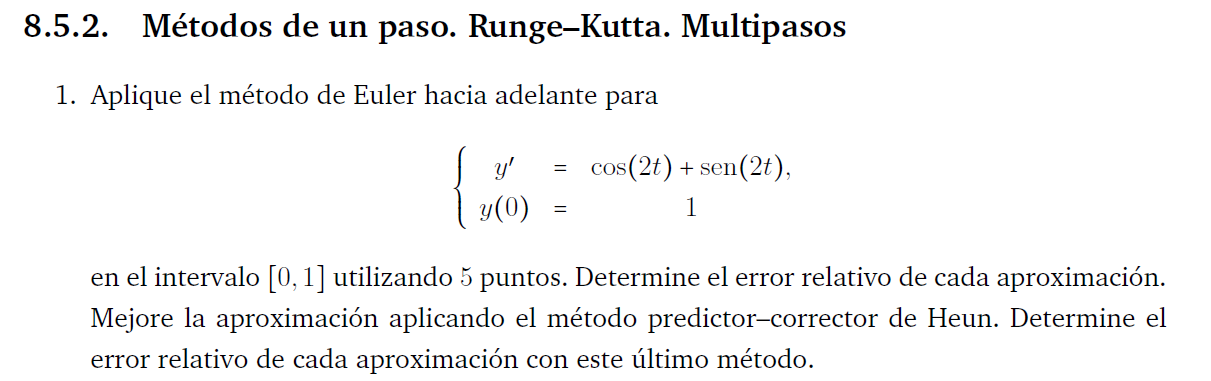

f=@(t,y) cos(2.*t)+sin(2.*t);

% Aproximaciones con Euler hacia adelante
T = Forward_Euler(f,0,1,1,4)

T =          0    1.0000
    0.2500    1.2500
    0.5000    1.5893
    0.7500    1.9347
    1.0000    2.2018


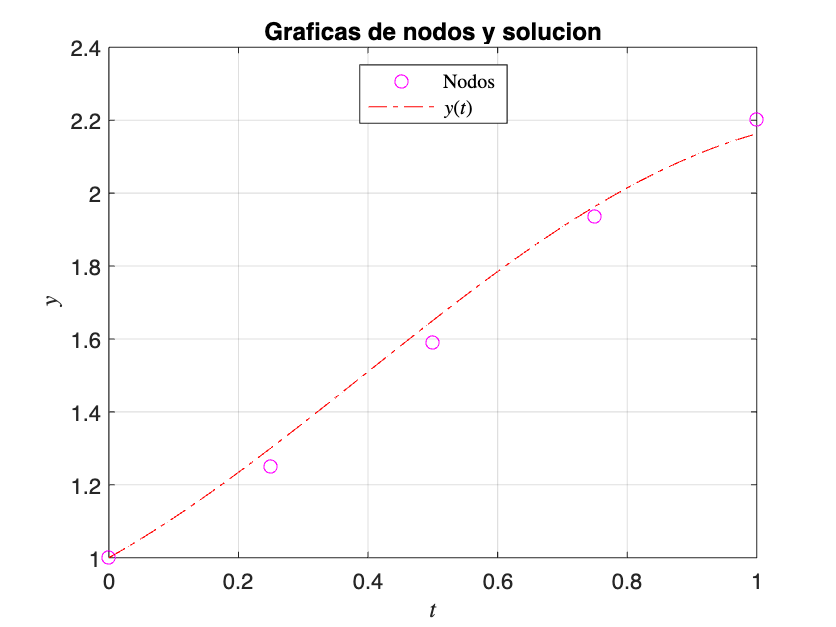


% Graficación nodos Euler adelante
x=0:0.01:1;
x1=T(:,1);
y1=T(:,2);
y=sin(2.*x)/2 - cos(2.*x)/2 + 3/2;
plot(x1, y1, 'mo', x,y,'r-.','Linewidth',0.5)
%axis([1 4 -1 'inf'])
grid on
title('Graficas de nodos y solucion')  % Fórmulas en LaTex
xlabel('$t$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('Nodos', '$y(t)$', ...
    'Location','north');
set(lg,'Interpreter','latex')


% Aproximaciones con el método del Trapecio explícito (Heun)
TH = Heun(f,0,1,1,4)

TH =          0    1.0000
    0.2500    1.2946
    0.5000    1.6370
    0.7500    1.9432
    1.0000    2.1384


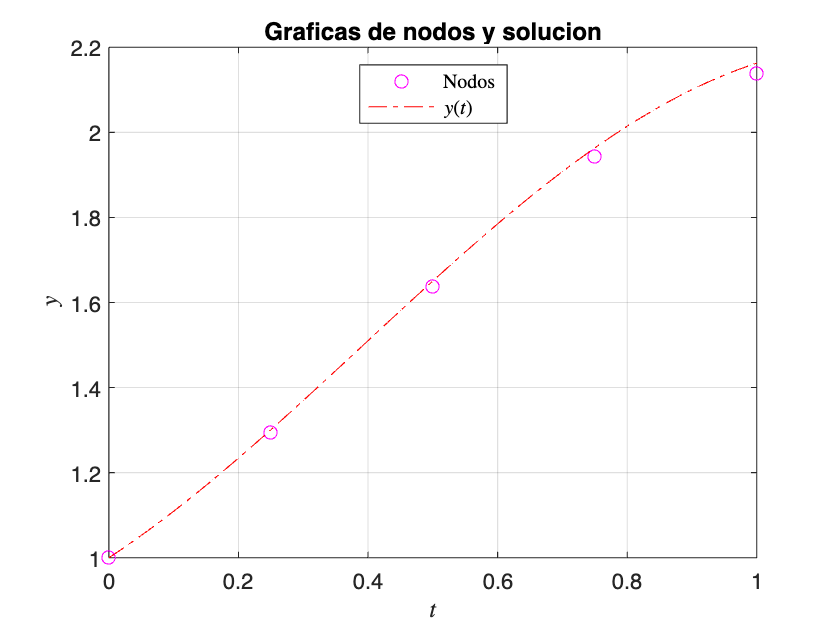


% Graficación nodos Heun
x=0:0.01:1;
x1=TH(:,1);
y1=TH(:,2);
y=sin(2.*x)/2 - cos(2.*x)/2 + 3/2;
plot(x1, y1, 'mo', x,y,'r-.','Linewidth',0.5)
%axis([1 4 -1 'inf'])
grid on
title('Graficas de nodos y solucion')  % Fórmulas en LaTex
xlabel('$t$', 'Interpreter','latex')
ylabel('$y$', 'Interpreter','latex')
lg=legend('Nodos', '$y(t)$', ...
    'Location','north');
set(lg,'Interpreter','latex')

Valores exactos de los $y(t_k)$s:

g=@(t) sin(2.*t)/2 - cos(2.*t)/2 + 3/2;
v=g(x1)

v =     1.0000
    1.3009
    1.6506
    1.9634
    2.1627



% Comparando las imágenes:

C = [T(:,1), T(:,2), TH(:,2) v]

C =          0    1.0000    1.0000    1.0000
    0.2500    1.2500    1.2946    1.3009
    0.5000    1.5893    1.6370    1.6506
    0.7500    1.9347    1.9432    1.9634
    1.0000    2.2018    2.1384    2.1627


***Runge-Kutta 2 ejemplo:***

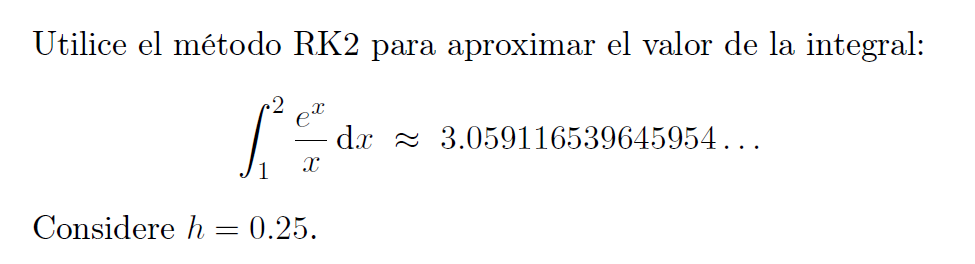

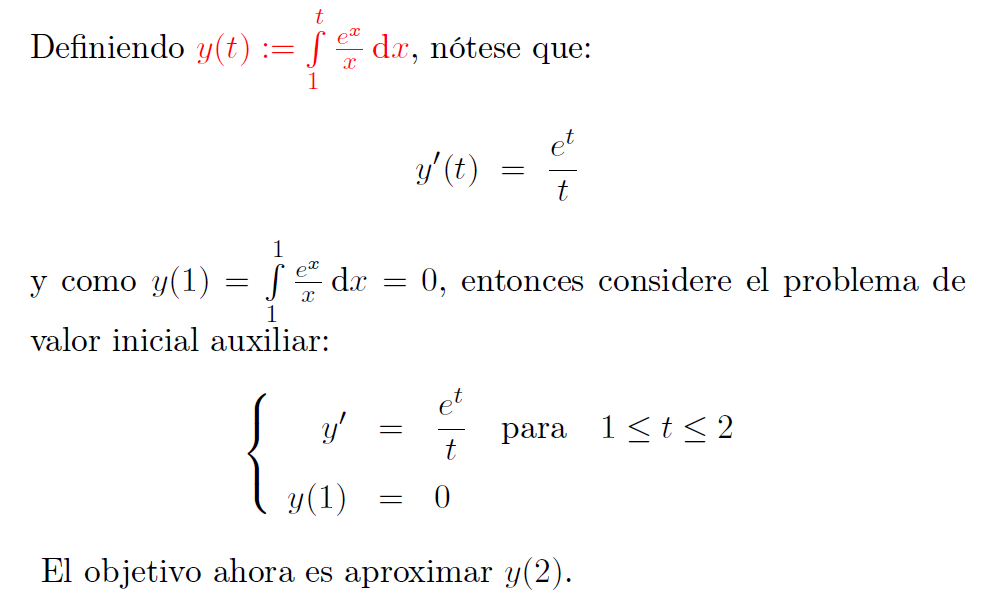

f = @(t,y) (exp(t))./t;

T_RK2= RK2(f, 1, 2, 0, 4)

T_RK2 =    1.000000000000000                   0
   1.250000000000000   0.684492633092896
   1.500000000000000   1.403597491805728
   1.750000000000000   2.184892728294971
   2.000000000000000   3.054335277672320



% integral exacta
format long; 
I = integral(@(t) exp(t)./t, 1, 2)

I =    3.059116539645954



% Probemos con RK4:
T_RK4= RK4(f, 1, 2, 0, 4)

T_RK4 =    1.000000000000000                   0
   1.250000000000000   0.685934930163119
   1.500000000000000   1.406174297618681
   1.750000000000000   2.188543501105164
   2.000000000000000   3.059124885513159



% Probemos con RK4, pero con más nodos:
%T_RK4= RK4(f, 1, 2, 0, 2000)

***Runge-Kutta 3 ejemplo:***

f=@(t,y) (3.*t.^2+4.*t-2)/(2*y-2);
M_RK3= RK3(f,0,1,-1,2)

M_RK3 =          0   -1.0000
    0.5000   -0.9015
    1.0000   -1.2311


***Ejercicio 7.2.2***

f=@(t,y) exp(-t.^2);
format;
T_RK3= RK3(f,0,1,0,4)

T_RK3 =          0         0
    0.2500    0.2449
    0.5000    0.4613
    0.7500    0.6302
    1.0000    0.7468



% Cálculo "exacto" de la integral definida
I_exacta=integral(@(x) exp(-x.^2), 0,1)

I_exacta = 0.7468

***Ejemplo presentación RK4***

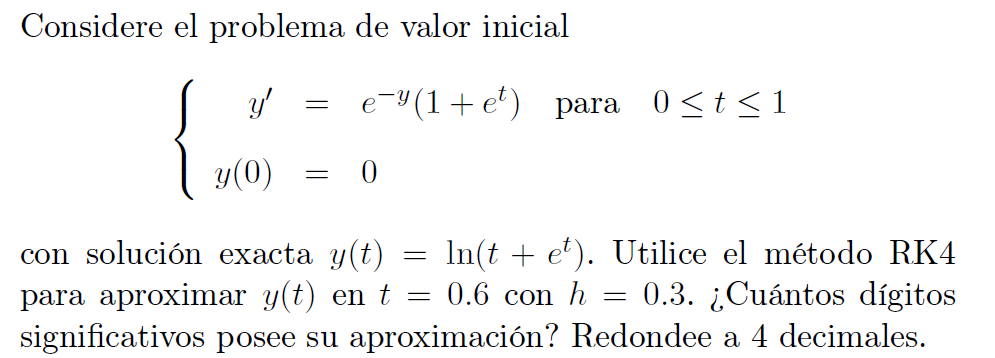

format long  
f = @(t,y) exp(-y)*(1 + exp(t));

T_RK4 = RK4(f, 0, 0.6, 0, 2)

T_RK4 =                    0                   0
   0.300000000000000   0.500719995653397
   0.600000000000000   0.884656883269629



% Haciendo h más pequeño:
%T_RK4 = RK4(f, 0, 0.6, 0, 1000)

% Valor exacto
yxact=log(0.6+ exp(0.6))

yxact =    0.884642694460790



% Con Euler hacia adelante
%[~, T] = Forward_Euler(f, 0, 0.6, 0, 1000)

***Ejemplo presentación AB3***

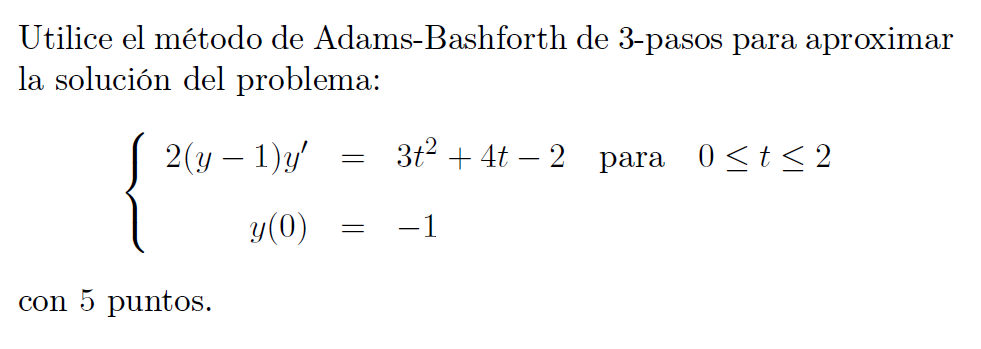

f=@(t,y) (3.*t.^2+4.*t-2)./(2*y-2);
T_AB3= AB3(f,0,2,-1,4)

T_AB3 =                    0  -1.000000000000000
   0.500000000000000  -0.901479963570127
   1.000000000000000  -1.231134089016191
   1.500000000000000  -2.069309507927677
   2.000000000000000  -3.041632865055450


Tgg =          0         0
    0.0393         0
    0.0785         0
    0.1178         0
    0.1571         0
    0.1963         0
    0.2356         0
    0.2749         0
    0.3142         0
    0.3534         0


***Ejemplo PC4 presentación:***

g=@(t,y) (3.*y*exp(t)-y.^2-1)/(y-exp(t));
MPC4 = PC4(g,0,1,2,5)

MPC4 =          0    2.0000
    0.2000    2.2999
    0.4000    2.7868
    0.6000    3.4422
    0.8000    4.2654
    1.0000    5.2729


***Ejercicio 7.3.3***

f=@(t,y) atan(y)-t*exp(t);
T_PC4 = PC4(f,-1.2,1.2,2,6)

T_PC4 =    -1.2000    2.0000
   -0.8000    2.6098
   -0.4000    3.2355
         0    3.8148
    0.4000    4.2403
    0.8000    4.3261
    1.2000    3.7470


## Funciones

***Euler hacia adelante***

function M = Forward_Euler(f,a,b,y0,N)
% Este metodo aproxima la solucion a la ecuacion diferencial 
% y' = f(t,y), a <= t <= b con condicion inicial y(a) = y0
% Entradas:  f(t,y) --- funcion
%             [a,b] --- intervalo
%                y0 ---- valor inicial
%                 N ---- numero de subintervalos
% Salidas:    M ---- matriz con aproximaciones y_i en t_i

h = (b-a)/N;
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ h*f(M(i,1), M(i,2));
end

end

***Método de Heun - Trapecio explícito***

function M = Heun(f,a,b,y0,N)
% Este metodo aproxima la solucion a la ecuacion diferencial 
% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Entradas:  f(t,y) --- funcion
%             [a,b] --- intervalo
%                y0 ---- valor inicial
%                 N ---- numero de subintervalos
% Salidas:    Tabla ---- tabla con aproximaciones en los puntos t_i

h = (b-a)/N;
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ h*f(M(i,1), M(i,2));
    M(i+1,2)= M(i,2) + (h/2)*(f(M(i,1), M(i,2)) + f(M(i+1,1), M(i+1,2)));
end

end

***Runge-Kutta 2 (RK2)***

function [M] = RK2(f,a,b,y0,N)
% Este metodo aproxima la solucion a la ecuacion diferencial 
% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Inputs:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- valor inicial
%             N ---- numero de subintervalos
% Output:     M ---- matriz con aproximaciones y_i en los puntos t_i

h = (b-a)/N;
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    k1 = f(M(i,1), M(i,2));
    k2 = f(M(i,1) + h/2, M(i,2) + (h/2)*k1); 
    M(i+1,2) = M(i,2)+ h*k2;
end
end

***Runge-Kutta 3 (RK3)***

function [M] = RK3(f,a,b,y0,N)
% Este metodo aproxima la solucion a la ecuacion diferencial 
% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Inputs:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- valor inicial
%             N ---- numero de subintervalos
% Output:     M ---- matriz con aproximaciones y_i en los puntos t_i

h = (b-a)/N;
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    k1 = f(M(i,1), M(i,2));
    k2 = f(M(i,1) + h/2, M(i,2) + (h/2)*k1); 
    k3 = f(M(i+1,1), M(i,2) + h*(2*k2-k1)); 
    M(i+1,2) = M(i,2)+ (h/6)*(k1+4*k2+k3);
end
end

***Runge-Kutta 4 (RK4)***

function [M] = RK4(f,a,b,y0,N)
% este metodo aproxima la solucion a la ecuacion diferencial 
% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Inputs:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- valor inicial
%             N ---- numero de subintervalos
% Output:     M ---- matriz con aproximaciones y_i en los puntos t_i

h = (b-a)/N;
M(1,1) = a; M(1,2) = y0;

for i=1:N
    M(i+1,1) = a+i*h;
    k1 = f(M(i,1), M(i,2));
    k2 = f(M(i,1) + h/2, M(i,2) + (h/2)*k1); 
    k3 = f(M(i,1) + h/2, M(i,2) + (h/2)*k2); 
    k4 = f(M(i+1,1), M(i,2) + h*k3); 
    M(i+1,2) = M(i,2)+ (h/6)*(k1+2*k2+2*k3+k4);
end
end

***Adams-Bashfort 2 pasos (AB2)***

function[M] = AB2(f,a,b,y0,N)
% este metodo aproxima la solucion a la ecuacion diferencial 
% usando el metodo de Adams-Bashford de 2 pasos, utilizando 
% el metodo de RK4 para aproximar las condiciones iniciales

% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Entradas:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- condicion inicial
%                 N ---- numero de subintervalos
% Salidas:        M ---- matriz con aproximaciones en los puntos t_i
h = (b-a)/N;
R = RK2(f,a,b,y0,N);    % se puede cambiar por otro RK

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);


for i = 2:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/2)*(3*f(M(i,1), M(i,2))-f(M(i-1,1), M(i-1,2)));
end
end

***Adams-Bashfort 3 pasos (AB3)***

function [M] = AB3(f,a,b,y0,N)
% este metodo aproxima la solucion a la ecuacion diferencial 
% usando el metodo de Adams-Bashford de 3 pasos, utilizando 
% el metodo de RK para aproximar las condiciones iniciales

% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Entradas:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- condicion inicial
%                 N ---- numero de subintervalos
% Salidas:        M ---- matriz con aproximaciones en los puntos t_i
h = (b-a)/N;
R = RK3(f,a,b,y0,N);    % se puede cambiar por otro RK

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);
M(3,1) = a+2*h; M(3,2) = R(3,2);


for i = 3:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/12)*(23*f(M(i,1), M(i,2))...
        -16*f(M(i-1,1), M(i-1,2))+5*f(M(i-2,1), M(i-2,2)));
end
end

***Adams-Bashfort 4 pasos (AB4)***

function[M] = AB4(f,a,b,y0,N)
% este metodo aproxima la solucion a la ecuacion diferencial 
% usando el metodo de Adams-Bashford de 4 pasos, utilizando 
% el metodo de RK4 para aproximar las condiciones iniciales

% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Entradas:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- condicion inicial
%                 N ---- numero de subintervalos
% Salidas:        M ---- matriz con aproximaciones en los puntos t_i
h = (b-a)/N;
R = RK4(f,a,b,y0,N);

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);
M(3,1) = a+2*h; M(3,2) = R(3,2);
M(4,1) = a+3*h; M(4,2) = R(4,2);

for i = 4:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/24)*( 55*f(M(i,1), M(i,2))...
        -59*f(M(i-1,1), M(i-1,2))+37*f(M(i-2,1), M(i-2,2))...
        -9*f(M(i-3,1), M(i-3,2)) );
end
end


***Adams-Moulton 2 pasos (AM2)***

function[M] = AM2(f,a,b,y0,N)
% este metodo aproxima la solucion a la ecuacion diferencial 
% usando el metodo de Adams-Moulton de 2 pasos, utilizando 
% el metodo de RK4 para aproximar las condiciones iniciales
% para predecir w_(i+1) en cada iteracion se usa RK4
% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Entradas:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- condicion inicial
%                 N ---- numero de subintervalos
% Salidas:        M ---- matriz con aproximaciones en los puntos t_i
h = (b-a)/N;
R = RK4(f,a,b,y0,N);

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);

for i = 2:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/12)*(5*f(M(i+1,1), R(i+1,2))...
    +8*f(M(i,1), M(i,2))-f(M(i-1,1), M(i-1,2)) );
end
end

***Adams-Moulton 3 pasos (AM3)***

function[M] = AM3(f,a,b,y0,N)
% este metodo aproxima la solucion a la ecuacion diferencial 
% usando el metodo de Adams-Moulton de 3 pasos, utilizando 
% el metodo de RK4 para aproximar las condiciones iniciales
% para predecir w_(i+1) en cada iteracion se usa RK4
% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Entradas:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- condicion inicial
%                 N ---- numero de subintervalos
% Salidas:        M ---- matriz con aproximaciones en los puntos t_i
h = (b-a)/N;
R = RK4(f,a,b,y0,N);

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);
M(3,1) = a+2*h; M(3,2) = R(3,2);

for i = 3:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/24)*( 9*f(M(i+1,1), R(i+1,2))...
    +19*f(M(i,1), M(i,2))-5*f(M(i-1,1), M(i-1,2))...
        + f(M(i-2,1), M(i-2,2)) );
end
end

***PC4***

function [M] = PC4(f,a,b,y0,N)
% este metodo aproxima la solucion a la ecuacion diferencial 
% usando el metodo PC4 = RK4+AB4+AM3 

% y' = f(t,y), a<= t <= b con condicion inicial y(a) = y0
% Entradas:  f(t,y) --- funcion
%             [a,b] --- intervalo
%             y0 ---- condicion inicial
%                 N ---- numero de subintervalos
% Salidas:        M ---- matriz con aproximaciones en los puntos t_i
h = (b-a)/N;
R = RK4(f,a,b,y0,N);

M(1,1) = a;     M(1,2) = y0;
M(2,1) = a+h;   M(2,2) = R(2,2);
M(3,1) = a+2*h; M(3,2) = R(3,2);
M(4,1) = a+3*h; M(4,2) = R(4,2);

for i = 4:N
    M(i+1,1) = a+i*h;
    M(i+1,2) = M(i,2)+ (h/24)*( 55*f(M(i,1), M(i,2))...
        -59*f(M(i-1,1), M(i-1,2))+37*f(M(i-2,1), M(i-2,2))...
        -9*f(M(i-3,1), M(i-3,2)) );
    
     M(i+1,2) = M(i,2)+ (h/24)*( 9*f(M(i+1,1), M(i+1,2))...
    +19*f(M(i,1), M(i,2))-5*f(M(i-1,1), M(i-1,2))...
        + f(M(i-2,1), M(i-2,2)) );
end
end